# Week 07 – Tuesday, Exercise 1 (Q1-1, Q1-2, Q1-3)

## Q1-1: CT Gaussian + CTFT

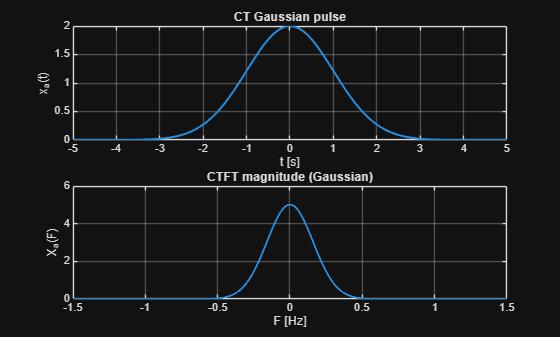

clear; close all; clc;

A0 = 2;
T0 = 1;

F0 = 1 / (2*pi*T0);

% Continuous-time and -frequency vectors (Q1-1)
timeCT = -20 : 0.1   : 20;     % seconds
freqCT = -5  : 0.001 : 5;      % Hz


xa = A0 * exp( -1/2 * (timeCT./T0).^2 );
Xa = A0 * sqrt(2*pi) * T0 .* exp( -(freqCT.^2) / (2*F0^2) );

% Plot results
figure;
subplot(2,1,1)
plot(timeCT, xa, 'LineWidth', 1.5);
xlabel('t [s]'); ylabel('x_a(t)');
title('CT Gaussian pulse');
xlim([-5 5]); grid on;

subplot(2,1,2)
plot(freqCT, Xa, 'LineWidth', 1.5);
xlabel('F [Hz]'); ylabel('X_a(F)');
title('CTFT magnitude (Gaussian)');
xlim([-1.5 1.5]); grid on;

## Q1-2: Sample + FFT (PDF: Fs=10 Hz, Ts=1/Fs, N=800, t=(n-0.5N)Ts)


% Given
Fs = 10; 
Ts = 1/Fs; 
N  = 800;

% a) time mapping and extremes
n_min = 1; 
n_max = N;
t_min = (n_min - 0.5*N) * Ts;
t_max = (n_max - 0.5*N) * Ts;

% Peak at t = 0 → (n - 0.5N)Ts = 0 → n_peak = 0.5N
n_peak = 0.5 * N;      % here: 400 (integer, since N=800)
t_peak = (n_peak - 0.5*N) * Ts;   % equals 0

fprintf('Q1-2(a): t_min = %.3f s, t_max = %.3f s, t_peak = %.3f s at n = %g\n', ...
        t_min, t_max, t_peak, n_peak);

Q1-2(a): t_min = -39.900 s, t_max = 40.000 s, t_peak = 0.000 s at n = 400



% b) n from 1..N
n  = 1:N;

% parameters from Exercise 1-1
A0 = 2; 
T0 = 1;

% sampled time vector
tS = (n - 0.5*N) * Ts;

% c) sampled Gaussian
x = A0 * exp( -1/2 * (tS./T0).^2 );

% d) DFT (unshifted)
X = fft(x);

fprintf('Q1-2(e): length(n) = %d, length(X) = %d (must be equal)\n', length(n), length(X));

Q1-2(e): length(n) = 800, length(X) = 800 (must be equal)


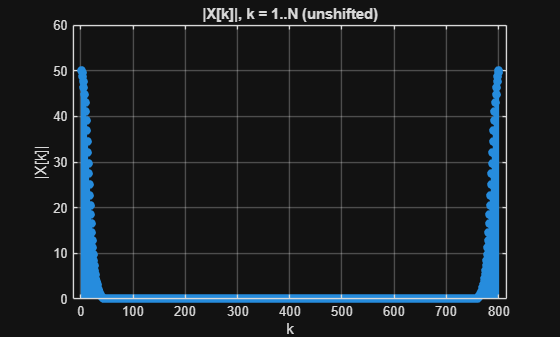



% f1) all samples
figure('Name','Q1-2(f) |X[k]| – all (unshifted)');
stem(1:N, abs(X), 'filled'); grid on;
xlabel('k'); ylabel('|X[k]|'); title('|X[k]|, k = 1..N (unshifted)');

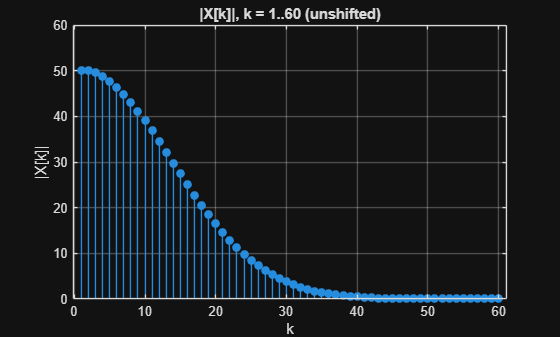


% f2) zoom k = 1..60
figure('Name','Q1-2(f) |X[k]| – k=1..60 (unshifted)');
index1 = 1:60;
stem(index1, abs(X(index1)), 'filled'); grid on;
xlabel('k'); ylabel('|X[k]|'); title('|X[k]|, k = 1..60 (unshifted)');

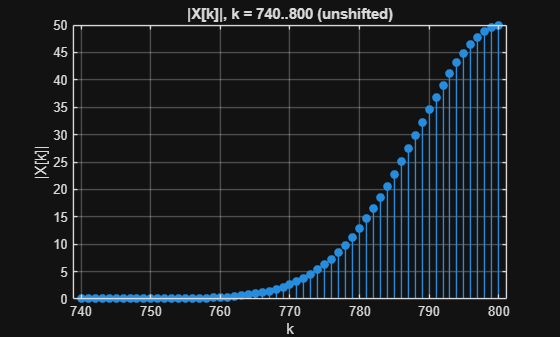


% f3) zoom k = N-60..N
figure('Name','Q1-2(f) |X[k]| – k=N-60..N (unshifted)');
index2 = (N-60):N;
stem(index2, abs(X(index2)), 'filled'); grid on;
xlabel('k'); ylabel('|X[k]|');
title(sprintf('|X[k]|, k = %d..%d (unshifted)', N-60, N));

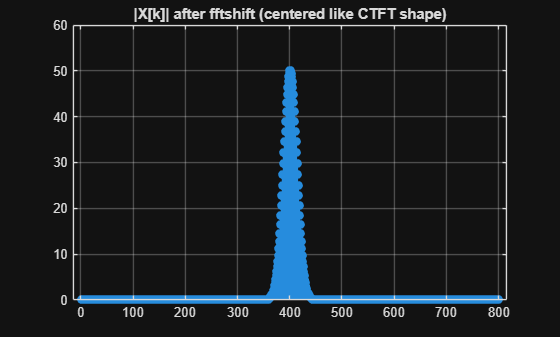


%g) Compare and discuss the shape of the plotted signal with the spectrum from exercise 1-1.
%Shape matches Gaussian from 1-1 (after centering with fftshift, it looks the same).
Xc = fftshift(X);
figure('Name','Q1-3 preview |X[k]| after fftshift');
stem(1:N, abs(Xc), 'filled'); grid on;
title('|X[k]| after fftshift (centered like CTFT shape)');


%h
%Amplitudes don't match directly because CTFT is continuous and FFT is unnormalized


## Q 1-3

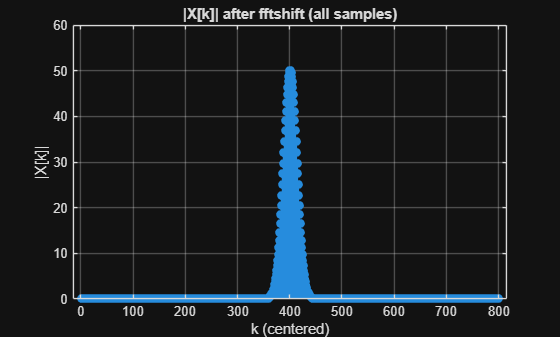


%% Q1-3: Center the spectrum with fftshift (as in the PDF)
Xc = fftshift(X);  % negative freqs left, DC in the middle, positive right

% (a) Plot all samples (centered)
figure('Name','Q1-3 |X[k]| after fftshift – all');
stem(1:N, abs(Xc), 'filled'); grid on;
xlabel('k (centered)'); ylabel('|X[k]|');
title('|X[k]| after fftshift (all samples)');

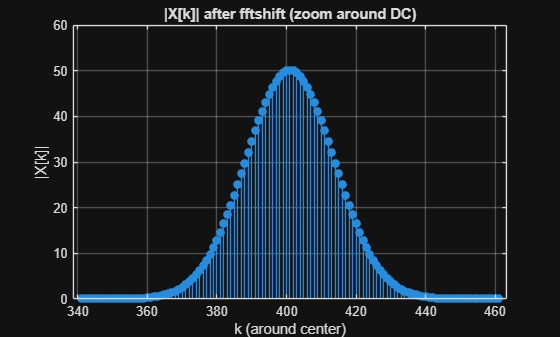


% (a) Zoom around the middle of X[k] (center bin)
mid = floor(N/2) + 1;          % index of DC after fftshift for even N
zoom_idx = (mid-60):(mid+60);  % ~120-sample window around center
figure('Name','Q1-3 |X[k]| after fftshift – center zoom');
stem(zoom_idx, abs(Xc(zoom_idx)), 'filled'); grid on;
xlabel('k (around center)'); ylabel('|X[k]|');
title('|X[k]| after fftshift (zoom around DC)');


% (b) Compare to Exercise 1-1 (shape)
% -> After fftshift, |X[k]| is a Gaussian centered at DC, matching the CTFT shape from Q1-1.

## Exercise 2 – Scaling of amplitude for FFT (DFT) spectra

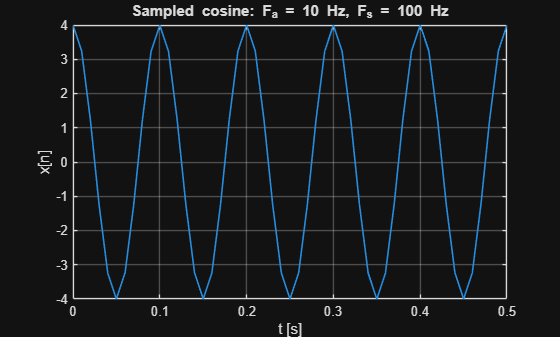

clear; close all; clc;

% Parameters
A  = 4;        % amplitude
Fa = 10;       % tone frequency [Hz]
Fs = 100;      % sampling frequency [Hz]
Ts = 1/Fs;
N1 = 1000;     % number of samples

% a) Sample index vector
n = 1:N1;

% b) Time vector
t = (n - 1) * Ts;   % [0, Ts, 2Ts, ..., (N1-1)Ts]

% c) Sampled cosine
x = A * cos(2*pi*Fa*t);

% Time plot (quick check)
figure; plot(t, x, 'LineWidth', 1.2); grid on;
xlabel('t [s]'); ylabel('x[n]'); xlim([0 0.5]);
title(sprintf('Sampled cosine: F_a = %g Hz, F_s = %g Hz', Fa, Fs));

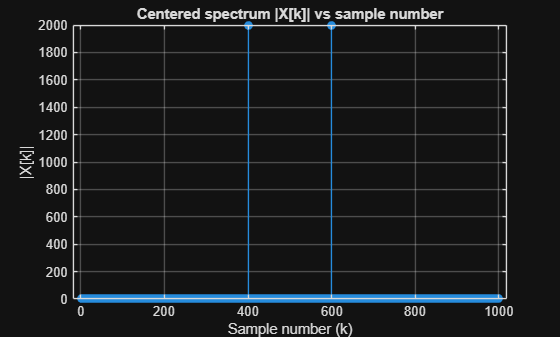


% d) Spectrum (DFT) and center it
X  = fft(x);          % unshifted
Xc = fftshift(X);     % centered

% e) Plot X[k] as function of sample number (use stem + abs), per PDF
figure;
stem(1:N1, abs(Xc), 'filled'); grid on;
xlabel('Sample number (k)'); ylabel('|X[k]|');
title('Centered spectrum |X[k]| vs sample number');

## Exercise 3-1

clear; close all; clc;
% Given from 2-1
Fs = 100;           % Hz
Ts = 1/Fs;          % s
N1 = 1000;          % samples
    
% a) Window, resolution, Nyquist
Tw   = N1 * Ts;         % total time window [s]
dF   = Fs / N1;         % frequency resolution [Hz]
Fnyq = Fs / 2;          % Nyquist [Hz]

fprintf('3-1(a): Tw = %.4f s,  ΔF = %.4f Hz,  F_Nyquist = %.1f Hz\n', Tw, dF, Fnyq);

3-1(a): Tw = 10.0000 s,  ΔF = 0.1000 Hz,  F_Nyquist = 50.0 Hz


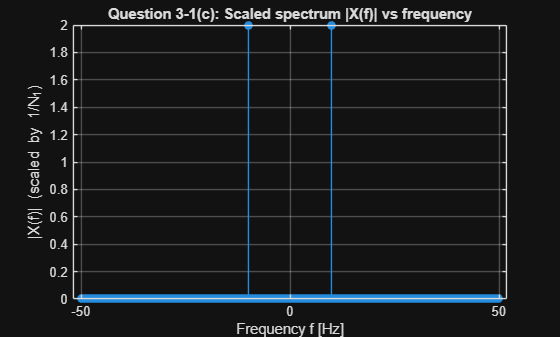


% b) Frequency vector corresponding to fftshift(X)
f = (-N1/2 : N1/2-1) * dF;   % spans ~[-Fs/2, Fs/2)

% Reuse your time signal from 2-1 (example):
A  = 4;      Fa = 10;               % tone and amplitude from 2-1
n  = 1:N1;   t  = (n-1)*Ts;
x  = A*cos(2*pi*Fa*t);

% Scaled spectrum and centered frequency axis
X_scaled  = fft(x) / N1;            % scale by N1
Xc_scaled = fftshift(X_scaled);     % center DC

% c) Plot scaled |X[k]| as a function of frequency
figure;
stem(f, abs(Xc_scaled), 'filled'); grid on;
xlabel('Frequency f [Hz]'); ylabel('|X(f)| (scaled by 1/N_1)');
title('Question 3-1(c): Scaled spectrum |X(f)| vs frequency');